# Plane Elasticity: Triangular Meshes

Consider a square plate of $2\times2\,\text{mm}$ and $0.5\,\text{mm}$ thickness, with a$1\,\text{mm}$ diameter hole at its center (see Figure). The plate is under a traction of $\tau = 10^3\,\text{N/mm}$ on its right edge, while its left edge is fixed. The Young modulus of the plate is $E=10^6\,\text{N/mm}^2$ and is Poisson's ratio is $\nu=0.25$.

                                 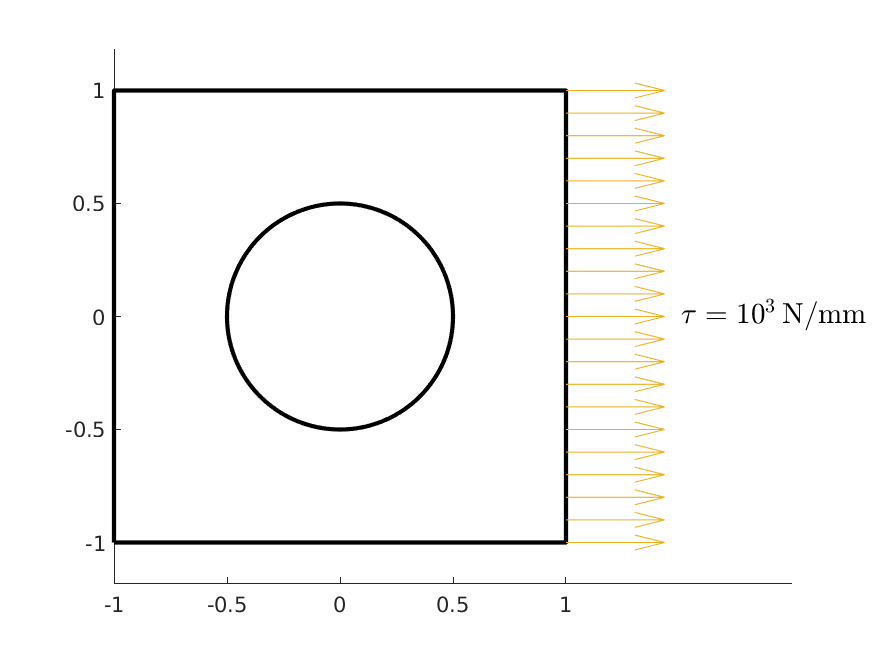

Using the meshing in $ \texttt{CircleHolemesh01.m}$, apply the FEM to find the displacements of the nodes, the stress-strain and the von Misses stress.

See Toni Susin's Blog "Numerical Factory" [FEM course, practice 4.2 ](https://numfactory.upc.edu/web/FiniteElements/Pract/P10-PlaneElasticity/html/PlaneElasticityTriangMesh.html)

clearvars
close all

excelFileDispl='displacements.xlsx';
excelFileStress = 'stress.xlsx';

modelProblem = 'stress';

t = 1000.0; %N/mm
E = 10e+6;  %Young modulus (N/mm^2)
mu = 0.25;  %Poosson's ratio (dimensionless)
th=0.5;     %Thickness (mm)
forceLoad = [1000.0;0]; %[Fx; Fy] traction on the right boundary (in N/mm)

eval('CircleHolemesh01');

[numNod,ndim]=size(nodes);
numElem = size(elem,1);

numbering = 0;
plotElements(nodes, elem, numbering);
hold on

Select nodes on the left (fixed) and on the right (under traction).

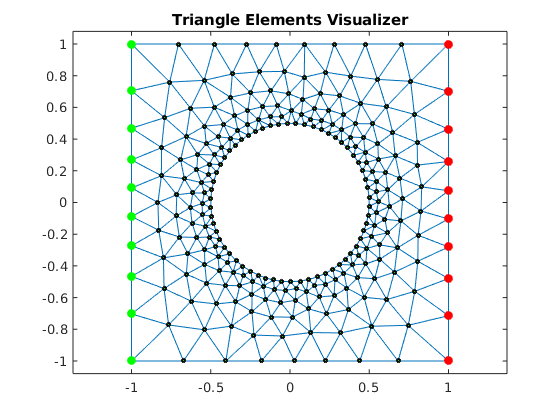

indLeft=find(nodes(:,1)< -0.99);
indRight= find(nodes(:,1) > 0.99);
plot(nodes(indLeft,1),nodes(indLeft,2),'o','MarkerFaceColor','green','MarkerEdgeColor','green')
plot(nodes(indRight,1),nodes(indRight,2),'o','MarkerFaceColor','red','MarkerEdgeColor','red')
hold off

#### Material properties

- modelProblem == 'stress': plane stress problem (thickness must be specified)

- modelProblem == 'strain': plane strain problem (thickness set to 1)

switch lower(modelProblem)
    case 'stress'
        c11=E/(1-mu^2);
        c22=c11;
        c12=mu*c11;
        c21=c12;
        c33=E/(2*(1+mu));   
    case 'strain'
        th=1;
        c11=E*(1-mu)/((1+mu)*(1-2*mu)); 
        c22=c11;
        c12=c11*mu/(1-mu);
        c21=c12;
        c33=E/(2*(1+mu));
    otherwise
        error('Please, specify whether it''s a ''stress'' or a ''strain'' problem!')
end
C = [c11, c12, 0; c21, c22, 0; 0, 0, c33];

K=zeros(numNod*ndim);
Q=zeros(numNod*ndim,1);
F=zeros(numNod*ndim,1);

for e=1:numElem
    %Ke=planeElastTriangStiffMatrixJR(nodes,elem,e,C); %<--- DO NOT use this!!!!
    Ke=planeElastTriangStiffMatrix(nodes,elem,e,C,th);
    rows=[
          ndim*elem(e,1)-1; ndim*elem(e,1); 
          ndim*elem(e,2)-1; ndim*elem(e,2);
          ndim*elem(e,3)-1; ndim*elem(e,3)
        ];
    cols = rows;
    K(rows,cols) = K(rows,cols) + Ke;
end


#### **Apply boundary conditions**

nodLoaded=indRight'; %nodes where the traction force is applied (transposed)
%Q=applyLoadsTriangJR(nodes,elem,nodLoaded,Q,forceLoad,1); %<--- DO NOT use this!
Q=applyLoadsTriang(nodes,elem,nodLoaded,Q,forceLoad);

u=zeros(ndim*numNod,1);
fixedNodes = [ndim*indLeft-1; ndim*indLeft];
freeNodes= setdiff(1:ndim*numNod,fixedNodes);

u(fixedNodes) = 0;


#### **Reduced system**

Km=K(freeNodes,freeNodes);
Qm=Q(freeNodes);

%Solve the reduced system
um=Km\Qm;
u(freeNodes,1) = um;


#### **Post-process**

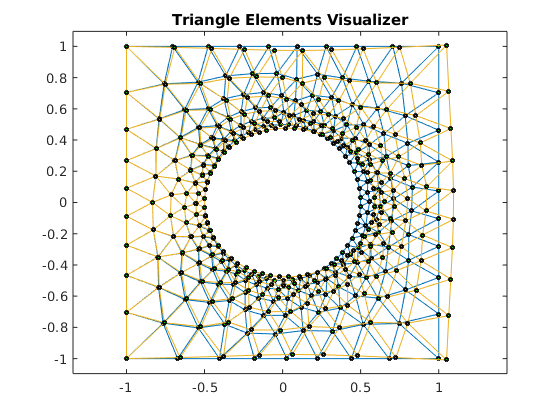


%Plot the displacements
scale=100;
plotPlaneNodElemDespl(nodes, elem, u, scale);

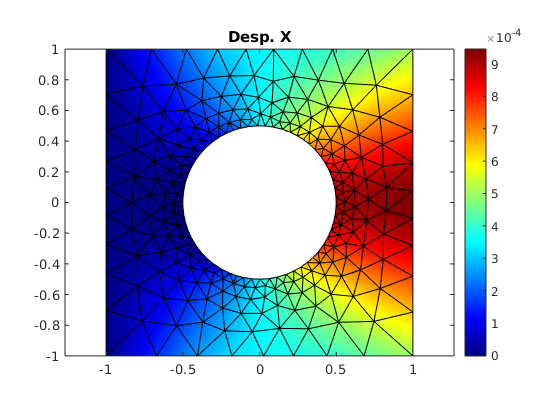

%Contour Solution: Desp.X
valueToShow=u(1:2:end,:);
titol='Desp. X';
colorTable='jet';
plotContourSolution(nodes,elem,valueToShow,titol,colorTable);

#### **Stress-strain & von Mises Stress**

**Remark:** for linear triangle elements the FEM method gives just a constant value of the stress tensor over each element

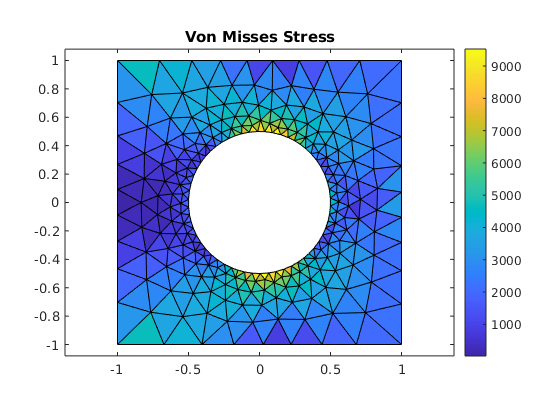

stress=zeros(3,numElem);
strain=zeros(3,numElem);
vonMises=zeros(numElem,1);

for e=1:numElem
    nods = elem(e,:);
    rows = [
            ndim*nods(1)-1;ndim*nods(1); ...
            ndim*nods(2)-1;ndim*nods(2); ...
            ndim*nods(3)-1;ndim*nods(3)
            ];
    x = nodes(nods,1);
    y = nodes(nods,2);
    beta = [y(2)-y(3), y(3)-y(1), y(1)-y(2)];
    gamma = [x(3)-x(2), x(1)-x(3), x(2)-x(1)];
    Area2 = det([ones(3,1),x,y]);
    B = [
          beta(1),  0,        beta(2),  0,        beta(3),  0;
          0,        gamma(1), 0,        gamma(2), 0,        gamma(3);
          gamma(1), beta(1),  gamma(2), beta(2),  gamma(3), beta(3)
         ]/Area2;
    ue=u(rows,1); 
    strain(:,e)=B*ue; %Constant at each element
    stress(:,e)=C*strain(:,e);
    sigmaX=stress(1,e);
    sigmaY=stress(2,e);
    tauXY = stress(3,e);
    vonMises(e,1)=sqrt(sigmaX^2+sigmaY^2-sigmaX*sigmaY+3*tauXY^2);
end

plotStressVM(nodes,elem,vonMises)

**Tables: displacements and stress**

% Displacements
format short e
displTable=table((1:numNod)',nodes(:,1),nodes(:,2),...
                  u(1:2:end),u(2:2:end),...
                  'VariableNames',{'NumNod','X','Y','UX','UY'});

%Write table to an Excel file                      
writetable(displTable,excelFileDispl);
%And show the displacements just for the last 10 nodes
displTable(end-9:end,:)

ans = 10×5 table
      NumNod          X              Y             UX            UY     
    __________    __________    ___________    __________    ___________

    2.5100e+02    8.2662e-01    -5.3671e-02    9.3031e-04    -5.7466e-06
    2.5200e+02    1.0000e+00     2.5850e-01    8.9109e-04     7.8482e-05
    2.5300e+02    1.0000e+00     4.6336e-01    7.8070e-04     1.0535e-04
    2.5400e+02    6.8197e-01    -1.0000e+00    4.3735e-04     6.6525e-05
    2.5500e+02    8.3100e-01     9.8970e-02    9.2239e-04     1.2574e-05
    2.5600e+02    1.0000e+00     7.3651e-02    9.4618e-04     2.5560e-05
    2.5700e+02    1.0000e+00     7.0241e-01    6.4869e-04     1.0372e-04
    2.5800e+02    1.0000e+00    -4.8001e-01    7.7225e-04    -1.0574e-04
    2.5900e+02    1.0000e+00    -1.0400e-01    9.3997e-04    -3.5284e-05
    2.600


% Table with the stress tensor SX, SY, SXY and von Misses
format short e
stress=stress';
stressTable=table((1:numElem)',stress(:,1),stress(:,2),stress(:,3),...
                  vonMises,...
                  'VariableNames',{'NumElem','SX','SY','SXY','VM'});
%Write table to an Excel file                      
writetable(stressTable,excelFileStress);                            
%And show the stress just for the last 10 results
stressTable(end-9:end,:)

ans = 10×5 table
     NumElem          SX             SY             SXY            VM    
    __________    ___________    ___________    ___________    __________

    4.1800e+02     1.5001e+03     3.2809e+02     2.2514e+02    1.4205e+03
    4.1900e+02     6.8230e+02     1.3627e+03    -9.8220e+01    1.1923e+03
    4.2000e+02     1.3222e+02    -8.8300e+01    -6.0777e+02    1.0701e+03
    4.2100e+02     1.5083e+03     2.7904e+02    -4.6924e+02    1.6102e+03
    4.2200e+02     6.6899e+02    -8.6097e+02     1.1811e+02    1.3441e+03
    4.2300e+02     7.5119e+01    -4.5914e+01     3.5811e+02    6.2924e+02
    4.2400e+02     1.5712e+02    -2.5507e+03     1.1473e+02    2.6402e+03
    4.2500e+02    -1.2523e+02    -1.1705e+03     3.4581e+02    1.2641e+03
    4.2600e+02    -1.9069e+02    -1.1964e+03    -2.9898e+02    1.2279e+0